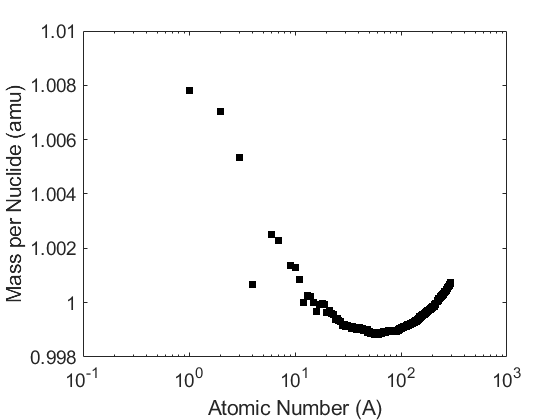

% Things we want to parse
As = [];
masses = [];

% Open the file
file = fopen('isotopeMasses.dat');

while ~feof(file)
    
    % Grab the line
    line = fgetl(file);
    
    % Split is by tabs
    entries = strsplit(line, "\t");
    
    % Find the mass
    for i = 1:length(entries)        
        if contains(entries(i), "(")
            break;
        end        
    end
    
    % Grab the A number
    A = str2double(entries(i-1));
    
    % Convert the mass into a double
    massString = entries{i};
    massString = strsplit(massString, "(");
    massString = massString{1};
    massString = strrep(massString, " ", "");
    mass = str2double(massString);
    
    % Add to array
    As(end+1) = A;
    masses(end+1) = mass;
    
    
end

fclose(file);

figure; hold on; box on;
scatter(As, masses./As, 'square', 'filled', 'MarkerEdgeColor', 'k', "MarkerFaceColor", 'k')
set(gca, 'XScale', 'log')
xlabel('Atomic Number (A)')
ylabel('Mass per Nuclide (amu)')
xlim([10^-1, 10^3])
ylim([0.998 1.01])
et(gca, 'FontSize', 14)